# The Spectrum of the JL operator

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev. For this example, we will define two different graphs, one with the uniform discretization and one with the Chebyshev discretization for the purpose of comparing the spectrum of the JL operator defined on each graph.

tag='dumbbell';
Phi = quantumGraphFromTemplate(tag,'discretization','Chebyshev','nX',32);
PhiUni = quantumGraphFromTemplate(tag);

## Spectrum of JL using Chebyshev points

First, we must generate solutions to the stationary problem.

diagramNumber=eigenfunctionsSaveData(Phi,tag,4,1,0);

Saved to directory data\dumbbell\005.
Run number is 5.


options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
[bn1,bl1]=continueFromEig(tag,diagramNumber,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\005\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.



filenumber=saveHighFrequencyStandingWave(tag,diagramNumber,-4,[1 2],[1 1]);

File saved to data\dumbbell\005\savedFunction.001.
File number is 1. 



options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
[bn2,bl2]=continueFromSaved(tag,diagramNumber,filenumber,-1,options);

N threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\005\branch002.
No branching bifurcations found.


Then, load the solution.

u = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'PhiColumn.010'));
muvec = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'LambdaVec'));
mu = muvec(10);

Define the JL operator then find its eigenvalues.

fcns = getGraphFcns(Phi);
JL = fcns.JL(u,0);
[V,lambda] = eigsJL(Phi,JL,102);

## Spectrum of JL using uniform points

We again begin with generating solutions to the stationary problem.

diagramNumber=eigenfunctionsSaveData(PhiUni,tag,4,1,0);

Saved to directory data\dumbbell\006.
Run number is 6.


options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
[bn1,bl1]=continueFromEig(tag,diagramNumber,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\006\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 8.
Branching Bifurcation at solution number 11.



filenumber=saveHighFrequencyStandingWave(tag,diagramNumber,-4,[1 2],[1 1]);

File saved to data\dumbbell\006\savedFunction.001.
File number is 1. 



options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
[bn2,bl2]=continueFromSaved(tag,diagramNumber,filenumber,-1,options);

N threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\006\branch002.
No branching bifurcations found.


Instead of just simply loading the solution, Newton's method must now be used to interpolate the data in order to ensure that it finds the solution that corresponds to the same mu (and thus same stationary problem) that was used earlier.

uguess = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'PhiColumn.010'));

fncsU = getGraphFcns(PhiUni);
ff=@(z) fcnsU.f(z,mu);
fM=@(z) fcnsU.fLinMatrix(z,mu);
tol=1e-8;
uUni = solveNewton(uguess,ff,fM,tol);

Define the JL operator then find its eigenvalues.

JLUni = fcnsU.JL(uUni,0);
[VUni,lambdaUni] = eigsJL(PhiUni,JLUni,102);

## Comparing JL spectrums from different discretizations

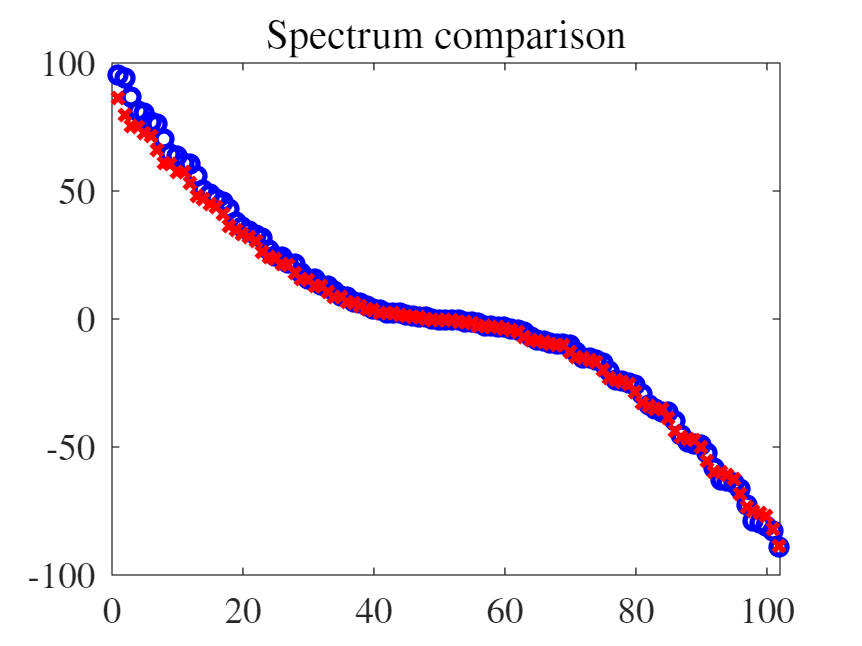

figure
plot(lambda,'bo')
hold on
plot(lambdaUni,'rx')
title('Spectrum comparison')

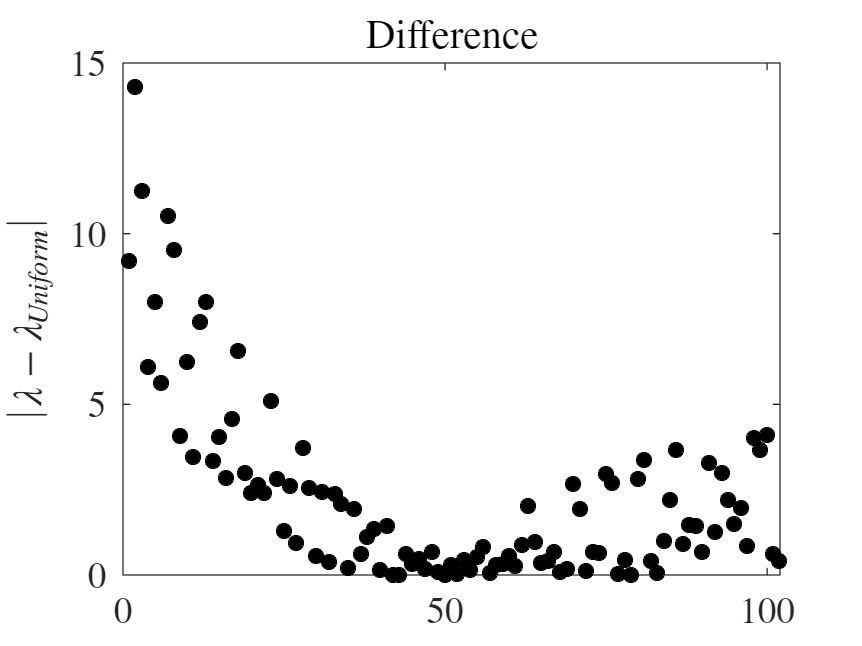


figure
plot(abs(lambda-lambdaUni),'k*')
title('Difference')
ylabel('$|\lambda-\lambda_{Uniform}|$')

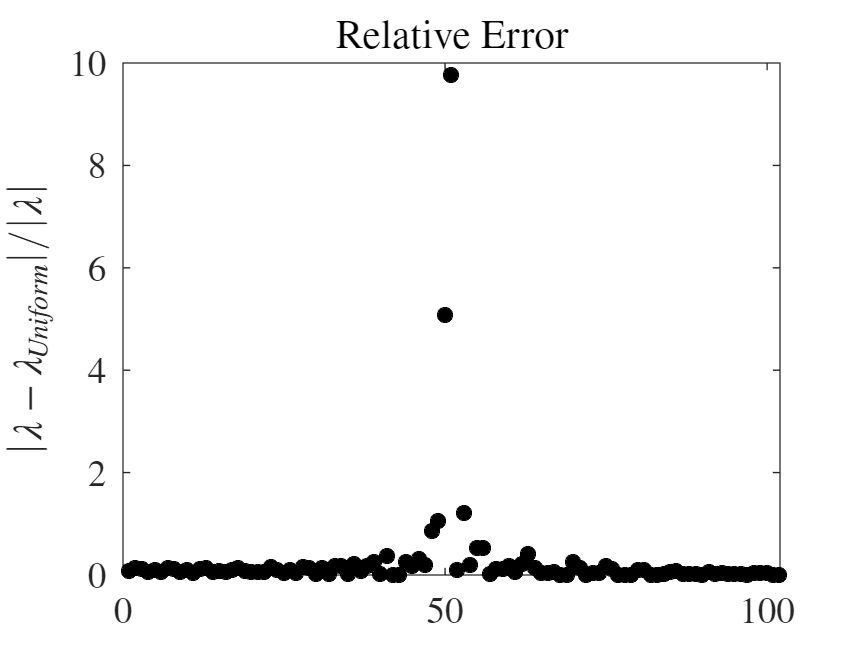


figure
plot(abs(lambda-lambdaUni)./abs(lambda),'k*')
title('Relative Error')
ylabel('$|\lambda-\lambda_{Uniform}|/|\lambda|$')